# Wavelet Image Denoising

The executable code file can be found at 

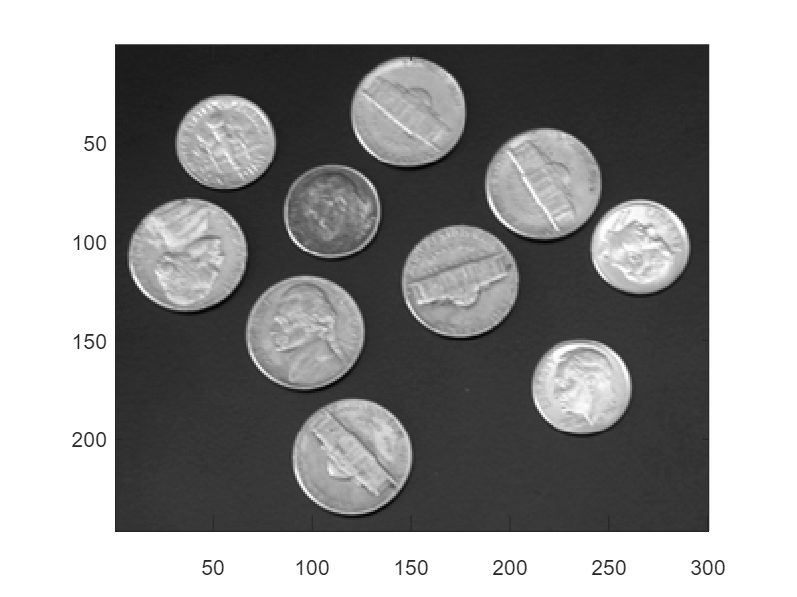

img = double(imread('coins.png'))/255; % change picture here
figure
imagesc(img)
if size(input, 3) == 1
    colormap(gray)
end
axis image


wavename = 'sym2'; % change wavelet here

### Suggestions for selecting pictures

**Grayscale images**: Choose `cameram.tif` or `coins.png` for a good display of detail and edge handling.

**Color images**: Choose `peppers.png` or `ngc6543a.jpg`, suitable for testing the wavelet performance of RGB images.

**Texture images**: Select `moon.tif` or `board.tif` to evaluate denoising performance on complex textures.

### Comparison of Different Wavelet

**Daubechies Wavelets **(`dbN)`: Higher-order Daubechies wavelets provide smoother reconstructions, making them suitable for signals with gradual changes. Lower-order wavelets are better for signals with sharp discontinuities, as they capture localized features effectively.

**Symlets** (`symN`): (Symmetrized version of Daubechies wavelets) Provide better preservation of symmetry and reduced edge artifacts compared to Daubechies wavelets. Lower-order symlets are useful for detailed signals with high-frequency components. Higher-order symlets are smooth and effective for noise removal in images with subtle gradients.

**Coiflets** (`coifN`): (Wavelets with additional vanishing moments for both the wavelet and scaling functions. Optimized for preserving signal energy during transformation) Particularly effective for signals with both high and low-frequency components. Useful in applications like biomedical signal processing and financial data denoising. Higher-order coiflets provide smoother reconstructions but may require more computation.

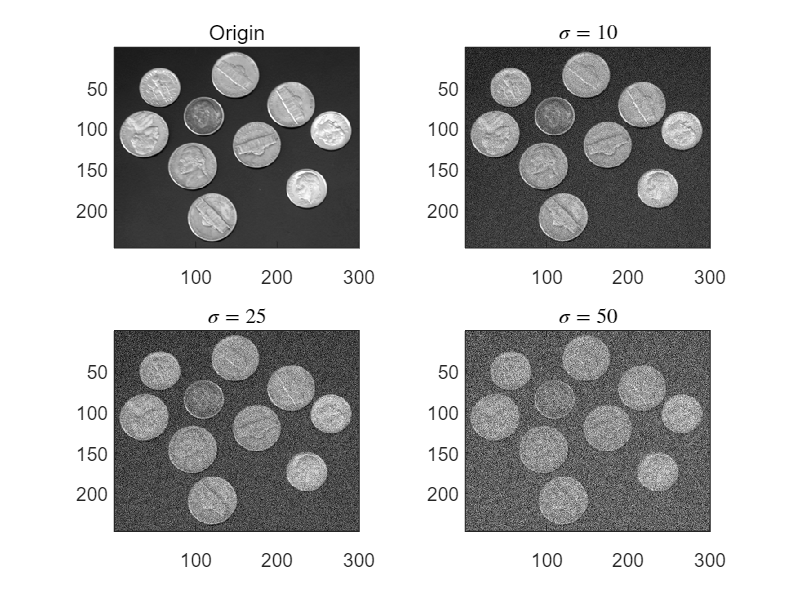

img_ori = img;
init = 2055615866; 
rng(init,"twister")

sigma = 1/255;
noise = sigma*randn(size(img_ori));

figure
if size(input, 3) == 1
    colormap(gray)
end

subplot(2,2,1)
imagesc(img_ori)
title("Origin")
axis image

subplot(2,2,2)
img_noise1 = img_ori+noise*10;
imagesc(img_noise1)
title("$\sigma = 10$","Interpreter","latex")
axis image

subplot(2,2,3)
img_noise2 = img_ori+noise*25;
imagesc(img_noise2)
title("$\sigma = 25$","Interpreter","latex")
axis image

subplot(2,2,4)
img_noise3 = img_ori+noise*50;
imagesc(img_noise3)
title("$\sigma = 50$","Interpreter","latex")
axis image

Hard Treshold 

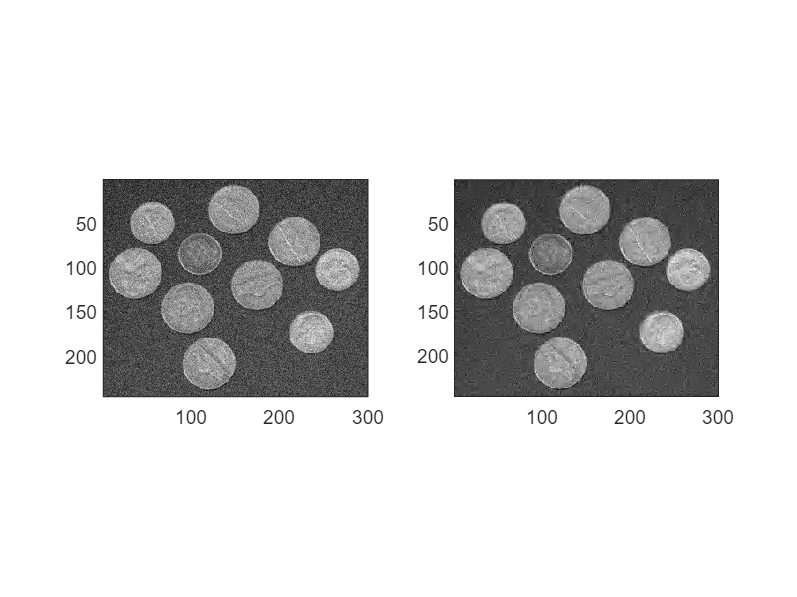

T = 50/255;  % threshold
input = img_noise2;
if size(input, 3) == 3
    [C1, S1] = wavedec2(input(:,:,1), 9, wavename);
    [C2, S2] = wavedec2(input(:,:,2), 9, wavename);
    [C3, S3] = wavedec2(input(:,:,3), 9, wavename);
    
    list = {C1, C2, C3};
    vars = {'C1', 'C2', 'C3'};
    % hard threshold
    for i = 1:numel(list)
        list{i} = list{i}.*(abs(list{i}) > T);
    end
    for i = 1:numel(vars)
        eval([vars{i} ' = list{i};']);
    end
    
    denoised1 = waverec2(C1, S1, wavename);
    denoised2 = waverec2(C2, S2, wavename);
    denoised3 = waverec2(C3, S3, wavename);
    denoised = cat(3, cat(3, denoised1, denoised2), denoised3);
else
    [C, S] = wavedec2(input, 9, wavename);
    C = C .* (abs(C) > T);
    denoised = waverec2(C, S, wavename);
end

SNR1 = SNR(input, denoised);

figure
if size(input, 3) == 1
    colormap(gray)
end
subplot(1,2,1)
imagesc(input)
axis image
subplot(1,2,2)
imagesc(denoised)
axis image

disp(['SNR = ' num2str(SNR1)])

SNR = 9.0491


Adaptive Treshold

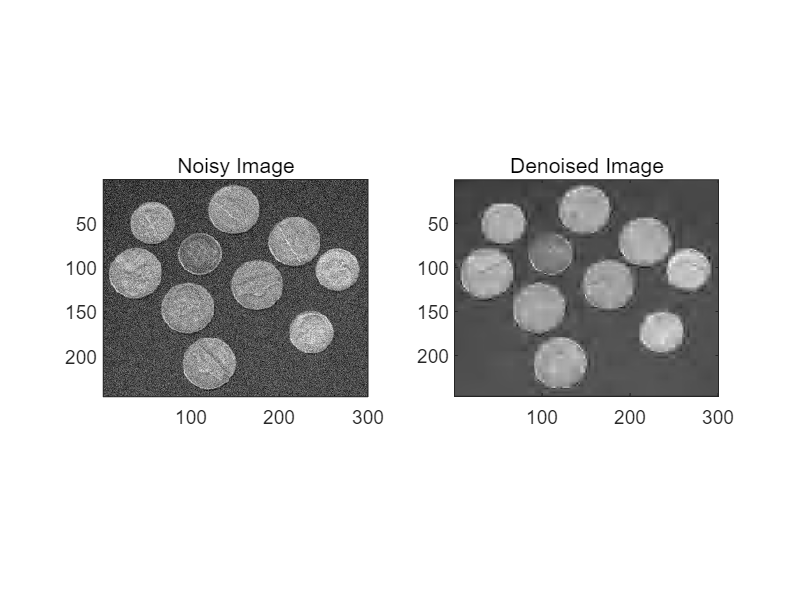

input = img_noise2;

if size(input, 3) == 3
    [C1, S1] = wavedec2(input(:,:,1), 9, wavename);
    [C2, S2] = wavedec2(input(:,:,2), 9, wavename);
    [C3, S3] = wavedec2(input(:,:,3), 9, wavename);
    
    list = {C1, C2, C3};
    vars = {'C1', 'C2', 'C3'};
    % Adaptive threshold
    for i = 1:numel(list)
        coeffs = list{i};
        sigma = median(abs(coeffs)) / 0.6745;  % Estimate noise standard deviation
        T = sigma * sqrt(2 * log(length(coeffs))); % Adaptive threshold
        list{i} = coeffs .* (abs(coeffs) > T);
    end
    for i = 1:numel(vars)
        eval([vars{i} ' = list{i};']);
    end
    
    denoised1 = waverec2(C1, S1, wavename);
    denoised2 = waverec2(C2, S2, wavename);
    denoised3 = waverec2(C3, S3, wavename);
    denoised = cat(3, cat(3, denoised1, denoised2), denoised3);
else
    [C, S] = wavedec2(input, 9, wavename);
    % Adaptive threshold
    sigma = median(abs(C)) / 0.6745;  % Estimate noise standard deviation
    T = sigma * sqrt(2 * log(length(C))); % Adaptive threshold
    C = C .* (abs(C) > T);
    denoised = waverec2(C, S, wavename);
end

SNR1 = SNR(input, denoised);

figure
if size(input, 3) == 1
    colormap(gray)
end
subplot(1,2,1)
imagesc(input)
axis image
title('Noisy Image')
subplot(1,2,2)
imagesc(denoised)
axis image
title('Denoised Image')

disp(['SNR = ' num2str(SNR1)])

SNR = 6.7089


function rt = SNR(input, estimate)
    % compute the signal-to-noise ratio of input and estimated image
    error = input - estimate;
    rt = 10 * log10(var(input(:), 1) / mean(error(:).^2));
end
